# Blackbody Radiation Lab

`Steven Henderson`

## *Part 1: Collecting Data*

The code section below shows the recorded data with each varible labeled with what data it holds.

% Recorded Data
Vp = [100, 110, 120, 130, 139.99, 149.98, 159.98, 169.98, 179.99, 189.99] ; % Power supply voltage (V)
Vp_uncer = [0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01] ;
V = [100.047, 110.054, 120.067, 130.080, 140.082, 150.089, 160.1, 170.108, 180.123, 190.138] ; % Voltage through bulb (V)
V_uncer = [0.05, 0.01, 0.005, 0.005, 0.1, 0.01, 0.01, 0.01, 0.01, 0.01] ;
I = [54.557, 57.754, 60.772, 63.711, 66.540, 69.318, 71.98, 74.563, 77.150, 79.610] ./ 1000 ; %  Current through bulb (A)
I_uncer = [0.1, 0.5, 0.5, 0.1, 0.1, 0.2, 0.2, 0.1, 0.1, 0.1] ./ 1000 ;
lambda_max = [738.091, 738.34, 740.585, 740.585, 739.981, 739.944, 739.302, 673.503, 571.928, 568.829] ./ 10^9; % Wavelength of max intensity (m)
lambda_max_uncer = [10, 10, 5, 7, 5, 6, 20, 5, 10, 5] ./ 10^9 ;
I_450062 = [1000, 1600, 2300, 3100, 4400, 6000, 8000, 5200, 6700, 8400] ./ 0.2 ; % Intensity at 450.062 nm (W/m^2)
I_450062_uncer = [100, 100, 100, 100, 100, 100, 100, 200, 200, 200] ./ 0.2 ;
I_50016 = [3525, 5225, 7810, 11500, 15500, 20900, 27400, 17200, 21800, 27000] ./ 0.2 ; % Intensity at 500.16 nm (W/m^2)
I_50016_uncer = [100, 225, 200, 250, 300, 200, 300, 400, 200, 300] ./ 0.2 ;
I_550165 = [8600, 13000, 18700, 26200, 34900, 45300, 53800, 37900, 46200, 52800] ./ 0.2 ; % Intensity at 550.165 nm (W/m^2)
I_550165_uncer = [200, 200, 300, 400, 300, 400, 300, 400, 500, 300] / 0.1 ;
I_60034 = [11800, 17000, 23800, 32200, 41900, 51400, 57400, 42700, 53000, 55400] ./ 0.1 ; % Intensity at 600.34 nm (W/m^2)
I_60034_uncer = [300, 200, 325, 390, 300, 300, 200, 400, 300, 300] ./ 0.1 ;
I_arr = [I_450062 ; I_50016 ; I_550165 ; I_60034] ; % Array of intensity at all wavelengths shown above ^
I_uncer_arr = [I_450062_uncer ; I_50016_uncer ; I_550165_uncer ; I_60034_uncer] ; 
lambdas = [450.062, 500.16, 550.165, 600.34] / 10^9 ;
% it = [200, 200, 200, 200, 200, 200, 200, 100, 100, 100] ; % Integration
% times (ms) used for normalization of the intensity measurements
% All wavelengths taken at a resolution of 100 nm 

Below is extra variables that needed to be calculated to complete the lab as well as uncertainity being propogated. For temperature, this equation was used,


$$T=\frac{T_{\textrm{room}} -60}{R_{\textrm{room}} }\frac{V}{I}+60,\textrm{where}\;R_{\textrm{room}\;} \textrm{is}\;\textrm{the}\;\textrm{resistance}\;\textrm{of}\;\textrm{the}\;\textrm{bulb}\;\textrm{at}\;\textrm{room}\;\textrm{temperature}\;\textrm{and}\;T_{\textrm{room}} \;\textrm{being}\;\textrm{room}\;\textrm{temperature}\ldotp$$


% Calculate needed varibles
T_0 = 298 ; % Room temperature
R_0 = 167.93 ; % Resistivity at room temperature
R_0_uncer = 0.05 ;
T = ((T_0 - 60) / R_0) .* (V ./ I) + 60 ; % Temperature (K)
logI_arr = log(I_arr) ; % Array of the log of intensities at certain wavelengths above
P = I .* V ; % Power
logP = log(P) ; % Natural log of Powers
logT = log(T) ; % Natural log of Temperatures
% Propagation of uncertainity
T_uncer = sqrt((-((T_0 - 60) / R_0^2) * (V ./ I)).^2.*R_0_uncer.^2 + (((T_0 - 60) / R_0) * (1 ./ I)).^2.*V_uncer.^2 + (-((T_0 - 60) / R_0) * (V ./ I.^2)).^2.*I_uncer.^2) ;
P_uncer = sqrt(I.^2.*V_uncer.^2 + V.^2.*I_uncer.^2) ;
logP_uncer = sqrt((1 ./ P.^2).*P_uncer.^2) ;
logT_uncer = sqrt((1 ./ T.^2).*T_uncer.^2) ;
logI_uncer_arr = sqrt((1 ./ I_arr.^2).*I_uncer_arr.^2) ;

## Part 2: Stefan Boltzmann Law

For this part we will take Stefan Boltzmann Law in this form,


$$\begin{array}{l}
P=e\sigma {\textrm{AT}}^4 \\
\ln \left(P\right)=\ln \left(e\sigma A\right)+4\ln \left(T\right)
\end{array}$$


Then we will plot ln(P) vs ln(T) and fit the data and find a slope of 4, confirming Stefan Boltzmann's Law.

% Confirming Stefan Boltzmann's equations
% Stefan-Boltzmann equation
% Here we are fitting ln(P) (power) vs. ln(T) (temperature)
% Our result should have a slope of 4  and an intercept of ln(epsilon*A*omega)
boltzmann_fit = wlsfit(logT, logP, logP_uncer) 

boltzmann_fit =   -29.3227    3.9340    0.0586    0.0073


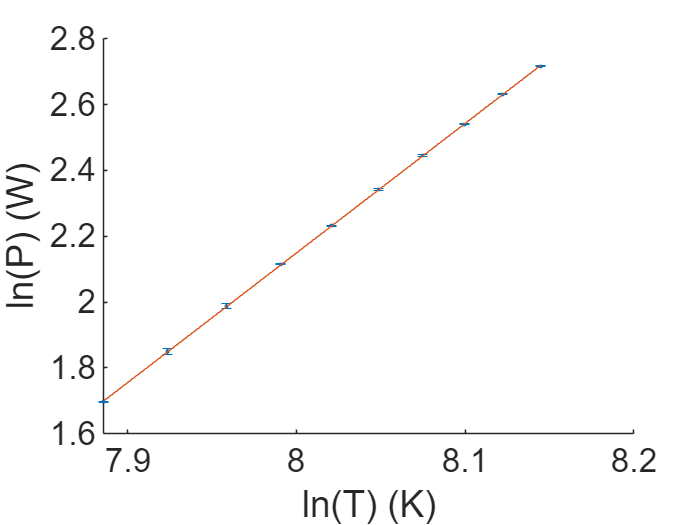

boltzmann_chi = findChi(logT, logP, logP_uncer, boltzmann_fit(2), boltzmann_fit(1)) ;
boltzmann_fit_equation = boltzmann_fit(1) + boltzmann_fit(2).*logT ;
% Plot Stefan-Boltzmann results
clf
hold on
errorbar(logT, logP, logP_uncer, 'Marker', '.', 'Linestyle', 'none')
plot(logT, boltzmann_fit_equation)
hold off
set(gca, 'fontsize', 20)
ylabel('ln(P) (W)')
xlabel('ln(T) (K)')

%subtitle(['$\chi^2$= ', num2str(boltzmann_chi(1)), ', $\chi_r^2$= ', num2str(boltzmann_chi(2))], 'Interpreter', 'latex')

**Analysis:**

Our slope was 3.92$\pm 0\ldotp 0001$. This is a good number but taking error into account, or answer is many sigma away. There must be a mistake in the error pipeline. My main suspect would be the equations not being correct as it does not take into account the error in the y-axis. Uncertainity here was calculated by watching fluctuations in the multimeters and fortunately or unfortunately, there were no fluctuations so the uncertainity was taken as the smallest decimal shown on the multimeters.

## Part 3: Wein's Law

For this we are confirming Wein's Law by taking it in the form,


$$\lambda_{\max } =\frac{2\ldotp 898\cdot {10}^{-3} \left(K\cdot m\right)}{T}$$


and then plotting the max intensity wavelength at each voltage against $\frac{1}{T}$ and finding a slope of $2\ldotp 898\cdot {10}^{-3} \;\left(K\cdot m\right)$

% Confirming Wein's Law
% Wein's Law
% Here we are fitting lambda_max (highest intenisty wavelength) vs. 1 / T (Temperature)
% Our result should have a slope of 2.898*10^-3
weins_fit = wlsfit((1 ./ T), lambda_max, lambda_max_uncer) 

weins_fit =    -0.0000    0.0022    0.0000    0.0001


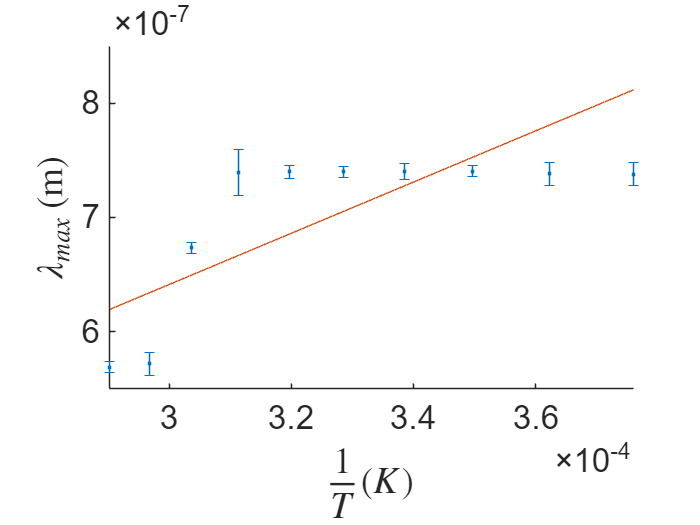

weins_chi = findChi((1 ./ T), lambda_max, lambda_max_uncer, weins_fit(2), weins_fit(1)) ;
weins_equation = weins_fit(1)  + weins_fit(2).*(1 ./ T) ;
clf
hold on
errorbar((1 ./ T), lambda_max, lambda_max_uncer, '.')
plot((1 ./ T), weins_equation)
hold off
set(gca, 'fontsize', 20)
xlabel('$\frac{1}{T} (K)$', 'Interpreter', 'latex')
ylabel('$\lambda_{max}$ (m)', 'Interpreter', 'latex')

%subtitle(['$\chi^2=$', num2str(round(weins_chi(1))), ', $\chi_r^2=$', num2str(weins_chi(2))], 'Interpreter','latex')

**Analysis:**

Our data was not good enough to observe this phenomena. We suspect this poor data comes from the fact that the max intensity was pushed into regions in the data that contained artifacts caused by the spectrometer we used. To get good data we would need to use different spectrometers and observe where the readings differ to determine a consistent max intesnity.

## Part 4:

In this part we are finding plancks constant by tanking intensity readings at four different consistent wavelengths while changing the voltage. Here we are plotting $\ln \left(I\right)$ vs $\frac{1}{T}$ and finding a slope that equals $-\frac{\textrm{hc}}{\lambda k}$ and takings plancks equation in the form of,


$$\begin{array}{l}
I\left(\lambda \right)=\frac{2\pi {\textrm{hc}}^2 }{\lambda^5 }\left\lbrack \frac{1}{e^{\frac{\textrm{hc}}{\lambda k_B T}} -1}\right\rbrack \\
\ln \left(I\right)=\ln \left(\frac{2\pi {\textrm{hc}}^2 }{\lambda^5 }\right)-\frac{\textrm{hc}}{\lambda k_B T}
\end{array}$$


and plotting $\ln \left(I\right)$ against $\frac{1}{T}$ and finding the slope. Then,

$\textrm{slope}=-\frac{\textrm{hc}}{\lambda k_B }$ so,


$$h=-\frac{\textrm{slope}\cdot \lambda k_B }{c}$$


and comparing this value to the actualy value of h.

% Confirming Plancks Law
% Planck's Law
% Here we are fitting ln(I) (Intensity) vs. 1 / T (Temperature)
% Our results should have a slope of -hc/lambda*k and an intercept of ln(2hc^2/epsilon)

% Get fits and chis
plancks_fits = zeros(4) ;
plancks_chis = zeros(4, 2) ;
for i = 1:length(logI_arr(:, 1))
    plancks_fits(i, :) = wlsfit((1 ./ T), logI_arr(i, :), logI_uncer_arr(i, :)) 
    plancks_chis(i, :) = findChi((1 ./ T), logI_arr(i, :), logI_uncer_arr(i, :), plancks_fits(i, 2), plancks_fits(i, 1)) ;
end

plancks_fits = 1.0e+04 *

    0.0017   -2.1678    0.0000    0.0490
         0         0         0         0
         0         0         0         0
         0         0         0         0


plancks_fits = 1.0e+04 *

    0.0017   -2.1678    0.0000    0.0490
    0.0017   -1.8456    0.0000    0.0235
         0         0         0         0
         0         0         0         0


plancks_fits = 1.0e+04 *

    0.0017   -2.1678    0.0000    0.0490
    0.0017   -1.8456    0.0000    0.0235
    0.0017   -1.6658    0.0000    0.0287
         0         0         0         0


plancks_fits = 1.0e+04 *

    0.0017   -2.1678    0.0000    0.0490
    0.0017   -1.8456    0.0000    0.0235
    0.0017   -1.6658    0.0000    0.0287
    0.0017   -1.3370    0.0000    0.0121


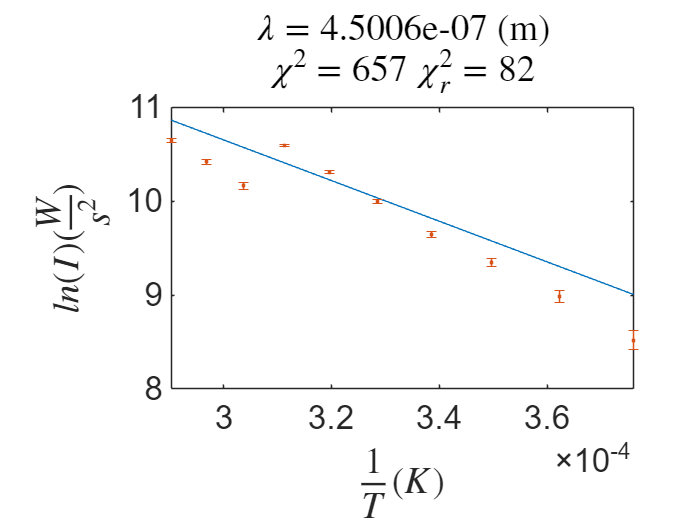

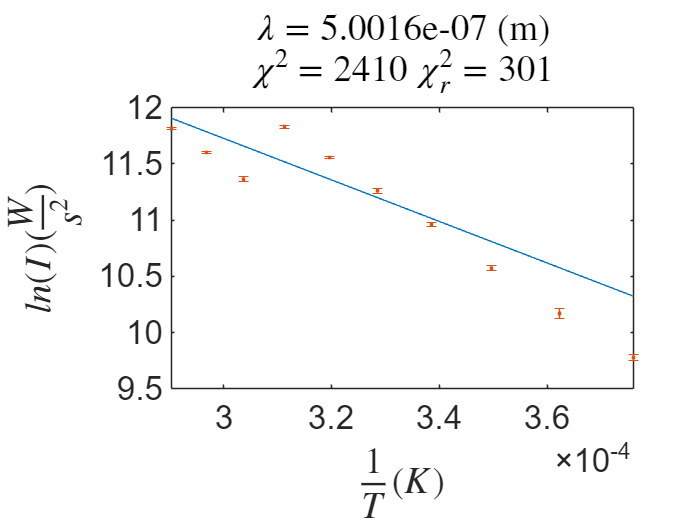

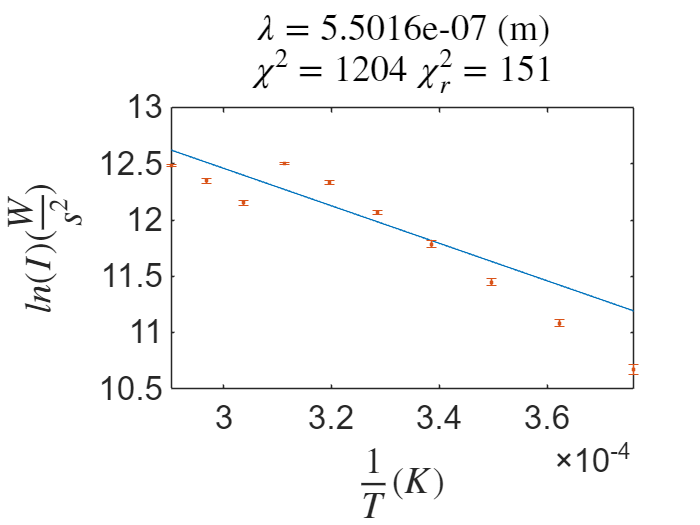

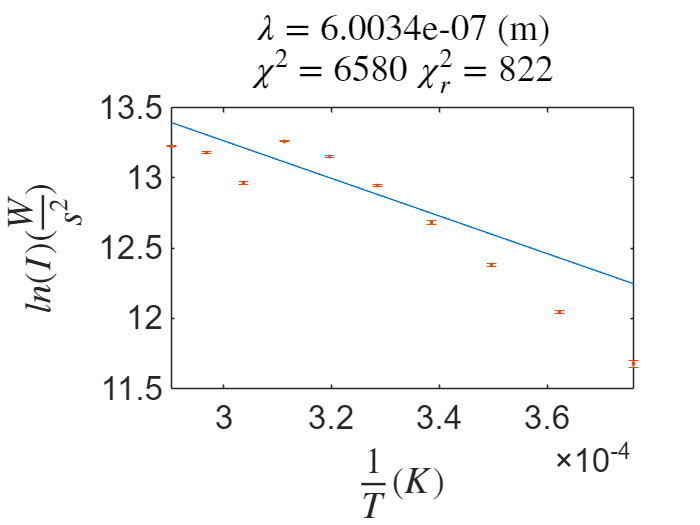


% Plot Plancks Results
clf
for i = 1:length(plancks_fits(1, :))
    figure
    plot((1 ./ T), plancks_fits(i, 1) + plancks_fits(i, 2).*(1 ./ T))
    hold on
    errorbar((1 ./ T), logI_arr(i, :), logI_uncer_arr(i, :), 'Linestyle', 'none', 'Marker', '.')
    hold off
    set(gca, 'fontsize', 20)
    xlabel('$\frac{1}{T} (K)$', 'Interpreter', 'latex')
    ylabel('$ln(I) (\frac{W}{s^2})$', 'Interpreter', 'latex')
    title(['$\lambda = $', num2str(lambdas(i)), ' (m)'], 'Interpreter', 'latex')
    subtitle(['$\chi^2 = $', num2str(round(plancks_chis(i, 1))), ' $\chi_r^2 = $', num2str(round(plancks_chis(i, 2)))], 'Interpreter', 'latex')
end

% Finding Plancks Constant
% Get estimated plancks constants
c = 3E8 ;
k = 1.38E-23 ;
h = 6.62607015E-34 ;
estimated_h = [0, 0, 0, 0] ;
estiamted_h_uncer = [0, 0, 0, 0] ;
for i = 1:length(lambdas)
    estimated_h(i) = -plancks_fits(i, 2)*lambdas(i)*k / c 
    estimated_h_uncer(i) = -(lambdas(i)*k/c)*plancks_fits(i, 4) 
end

estimated_h = 1.0e-33 *

    0.4488         0         0         0


estimated_h_uncer = -1.0144e-35

estimated_h = 1.0e-33 *

    0.4488    0.4246         0         0


estimated_h_uncer = 1.0e-34 *

   -0.1014   -0.0540


estimated_h = 1.0e-33 *

    0.4488    0.4246    0.4216         0


estimated_h_uncer = 1.0e-34 *

   -0.1014   -0.0540   -0.0727


estimated_h = 1.0e-33 *

    0.4488    0.4246    0.4216    0.3692


estimated_h_uncer = 1.0e-34 *

   -0.1014   -0.0540   -0.0727   -0.0335


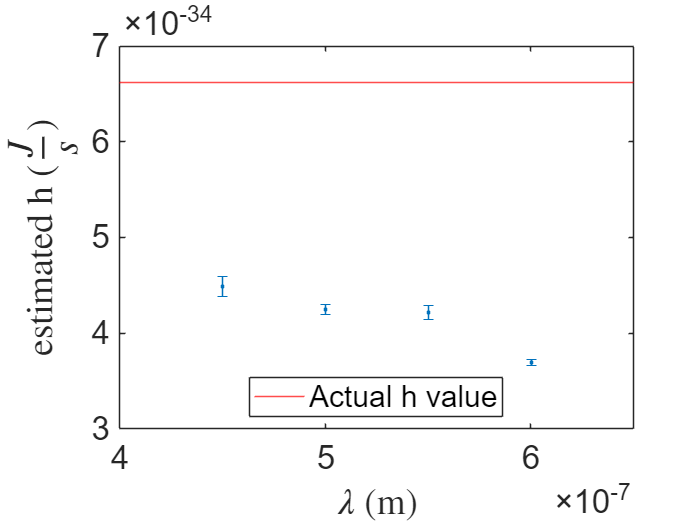


% Plot estimated plancks constant vs lambdas and then plot actual plancks constant
clf
errorbar(lambdas, estimated_h, estimated_h_uncer, 'LineStyle', 'none', 'Marker','.')
hold on
yline(h, 'r')
hold off
xlabel('$\lambda$ (m)', 'Interpreter', 'latex')
ylabel('estimated h ($\frac{J}{s}$)', 'Interpreter', 'latex')
set(gca, 'fontsize', 20)
legend('', 'Actual h value', 'Location', 'south')
xlim([4e-7, 6.5e-7])

This data is close but not close enough to call it conclusive. We found that the first three data points for every wavelength had a shift in intensity which we believe was caused by the change in intergration time (how long the computer waits before collecting data) at different voltages. In this next part we will remove those data points and see if we can get closer values of h.

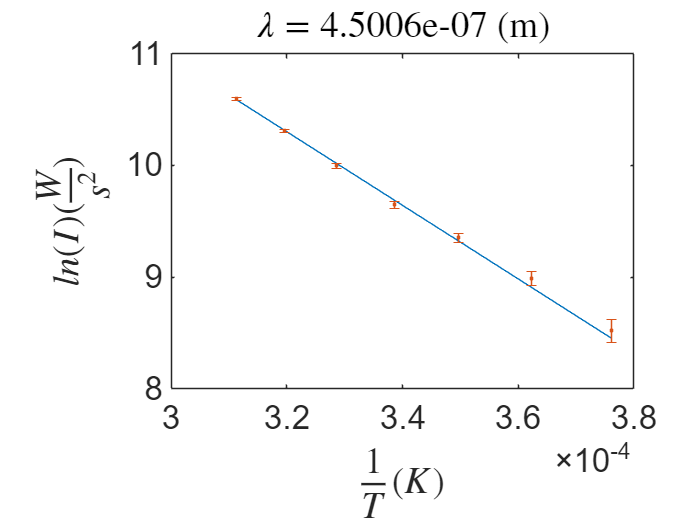

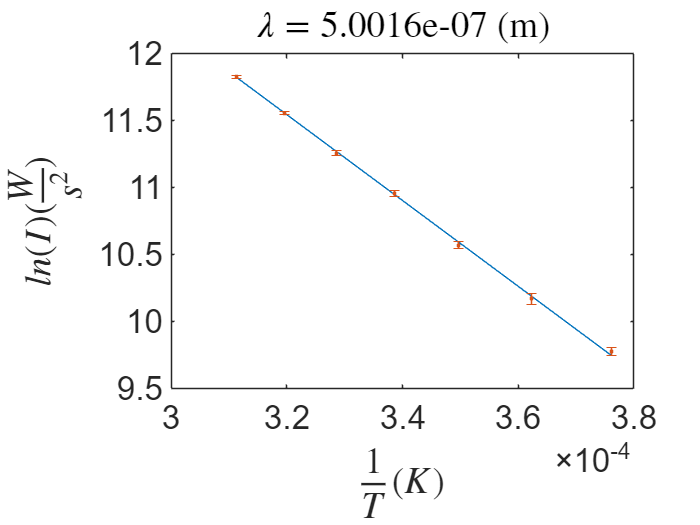

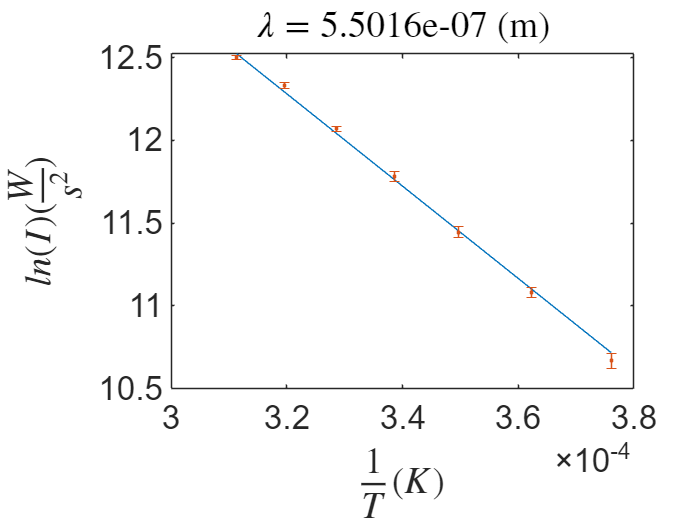

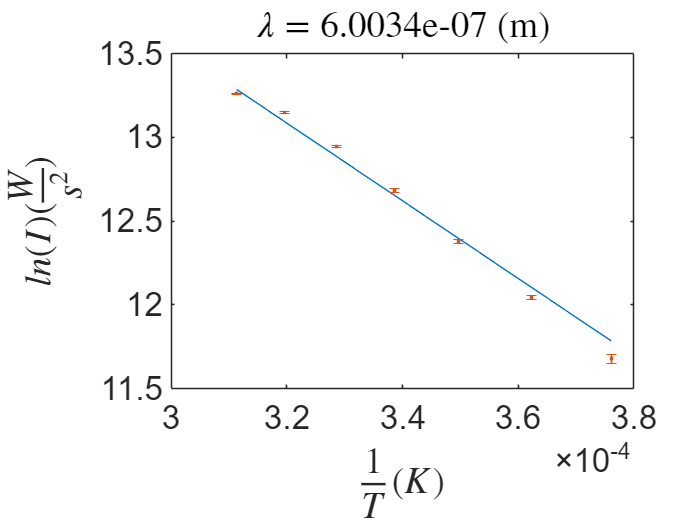

% Confirming Plancks Law with only the last 7 data points for reasons above
% Planck's Law
% Here we are fitting ln(I) (Intensity) vs. 1 / T (Temperature)
% Our results should have a slope of -hc/lambda*k and an intercept of ln(2hc^2/epsilon)
% Change data to only use first 7 (last 7 data on graphs)
T = T(1:7) ;
logI_arr = logI_arr(:, 1:7) ;
logI_uncer_arr = logI_uncer_arr(:, 1:7) ;
% Get fits and chis
plancks_fits = zeros(4) ;
plancks_chis = zeros(4, 2) ;
for i = 1:length(logI_arr(:, 1))
    plancks_fits(i, :) = wlsfit((1 ./ T), logI_arr(i, :), logI_uncer_arr(i, :)) ;
    plancks_chis(i, :) = findChi((1 ./ T), logI_arr(i, :), logI_uncer_arr(i, :), plancks_fits(i, 2), plancks_fits(i, 1)) ;
end

% Plot Plancks Results
clf
for i = 1:length(plancks_fits(1, :))
    figure
    plot((1 ./ T), plancks_fits(i, 1) + plancks_fits(i, 2).*(1 ./ T))
    hold on
    errorbar((1 ./ T), logI_arr(i, :), logI_uncer_arr(i, :), 'Linestyle', 'none', 'Marker', '.')
    hold off
        set(gca, 'fontsize', 20)
    xlabel('$\frac{1}{T} (K)$', 'Interpreter', 'latex')
    ylabel('$ln(I) (\frac{W}{s^2})$', 'Interpreter', 'latex')
    title(['$\lambda = $', num2str(lambdas(i)), ' (m)'], 'Interpreter', 'latex')
    %subtitle(['$\chi^2 = $', num2str(round(plancks_chis(i, 1))), ' $\chi_r^2 = $', num2str(round(plancks_chis(i, 2)))], 'Interpreter', 'latex')
end

% Get estimated plancks constants
c = 3E8 ;
k = 1.38E-23 ;
h = 6.62607015E-34 ;
estimated_h = [0, 0, 0, 0] ;
estiamted_h_uncer = [0, 0, 0, 0] ;
for i = 1:length(lambdas)
    estimated_h(i) = -plancks_fits(i, 2)*lambdas(i)*k / c 
    estimated_h_uncer(i) = -(lambdas(i)*k/c)*plancks_fits(i, 4) 
end

estimated_h = 1.0e-33 *

    0.6818         0         0         0


estimated_h_uncer = 1.0e-34 *

   -0.1400   -0.0540   -0.0727   -0.0335


estimated_h = 1.0e-33 *

    0.6818    0.7363         0         0


estimated_h_uncer = 1.0e-34 *

   -0.1400   -0.0857   -0.0727   -0.0335


estimated_h = 1.0e-33 *

    0.6818    0.7363    0.7053         0


estimated_h_uncer = 1.0e-34 *

   -0.1400   -0.0857   -0.1122   -0.0335


estimated_h = 1.0e-33 *

    0.6818    0.7363    0.7053    0.6399


estimated_h_uncer = 1.0e-34 *

   -0.1400   -0.0857   -0.1122   -0.0485


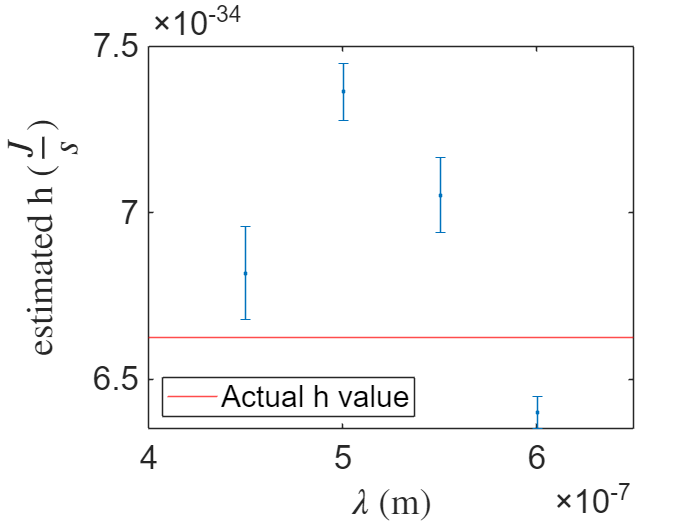


% Plot estimated plancks constant vs lambdas and then plot actual plancks constant
clf
errorbar(lambdas, estimated_h, estimated_h_uncer, 'LineStyle', 'none', 'Marker','.')
hold on
yline(h, 'r')
hold off
xlabel('$\lambda$ (m)', 'Interpreter', 'latex')
ylabel('estimated h ($\frac{J}{s}$)', 'Interpreter', 'latex')
set(gca, 'fontsize', 20)
legend('', 'Actual h value', 'Location', 'southwest')
xlim([4e-7, 6.5e-7])

**Analysis:**

Running the code without the first three data points shows much better results. It is important to note with $\lambda =600\;\textrm{nm}$ the chi square values are very poor so that estimate of h can be ommited. Without that measurement we find very close estimates of h to the actual value of h. The estimated h value vary from 1.2 $\sigma$ away to 5 $\sigma$ away.

## Functions used for finding fits and chi squares.

% Function for calculating linear fit by weighted least squares
function fit = wlsfit(x, y, y_uncer)
    weights = 1 ./ y_uncer.^2 ;
    delta = sum(weights)*sum(weights.*(x.^2)) - (sum(weights.*x))^2 ;
    A = (sum(weights.*x.^2)*sum(weights.*y) - sum(weights.*x)*sum(weights.*x.*y)) / delta ;
    B = (sum(weights)*sum(weights.*x.*y) - sum(weights.*x)*sum(weights.*y)) / delta ; 
    A_err = sqrt(sum(weights.*x.^2) / delta) ;
    B_err = sqrt(sum(weights) / delta) ;
    % Return in form fit = A + Bx
    fit = [A, B, A_err, B_err] ;
end

% Function for finding chi-square and reduced chi-square with poly1 as the
% fit
function chi = findChi(xdata, ydata, ydataerr, slope, offset)
    % chisq inputs: xdata, ydata, ydata errors, best fit slope and offset
    % outpus: chi2 and reduced chi2
    weights = 1./(ydataerr.^2) ; % find weights from errors
    myfit = slope.*xdata + offset; % find best linear fit
    chi2 = sum(((ydata-myfit).^2).*weights) ;
    n = size(xdata,2) ; % # of data elements
    rchi2 = chi2/(n-2) ; % # of degrees of freedom
    chi = [chi2, rchi2] ;
end